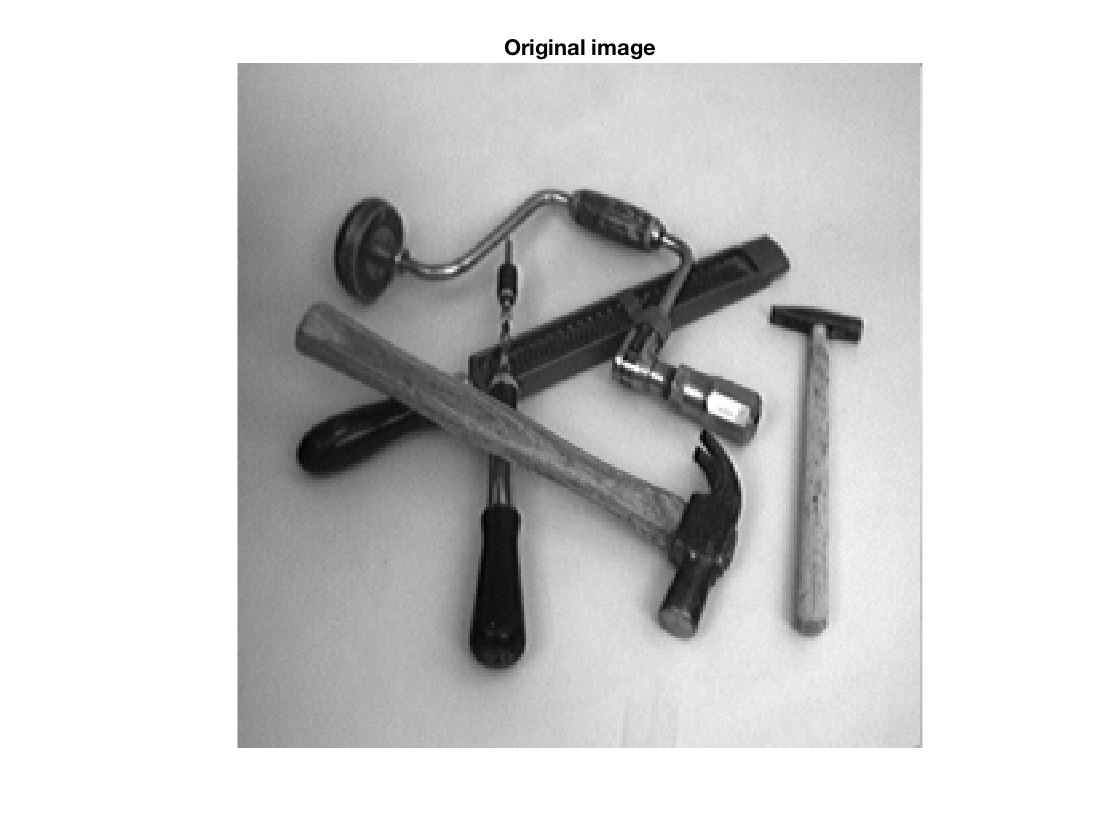

% Q1
tools = few256;
showgrey(tools);
title("Original image");

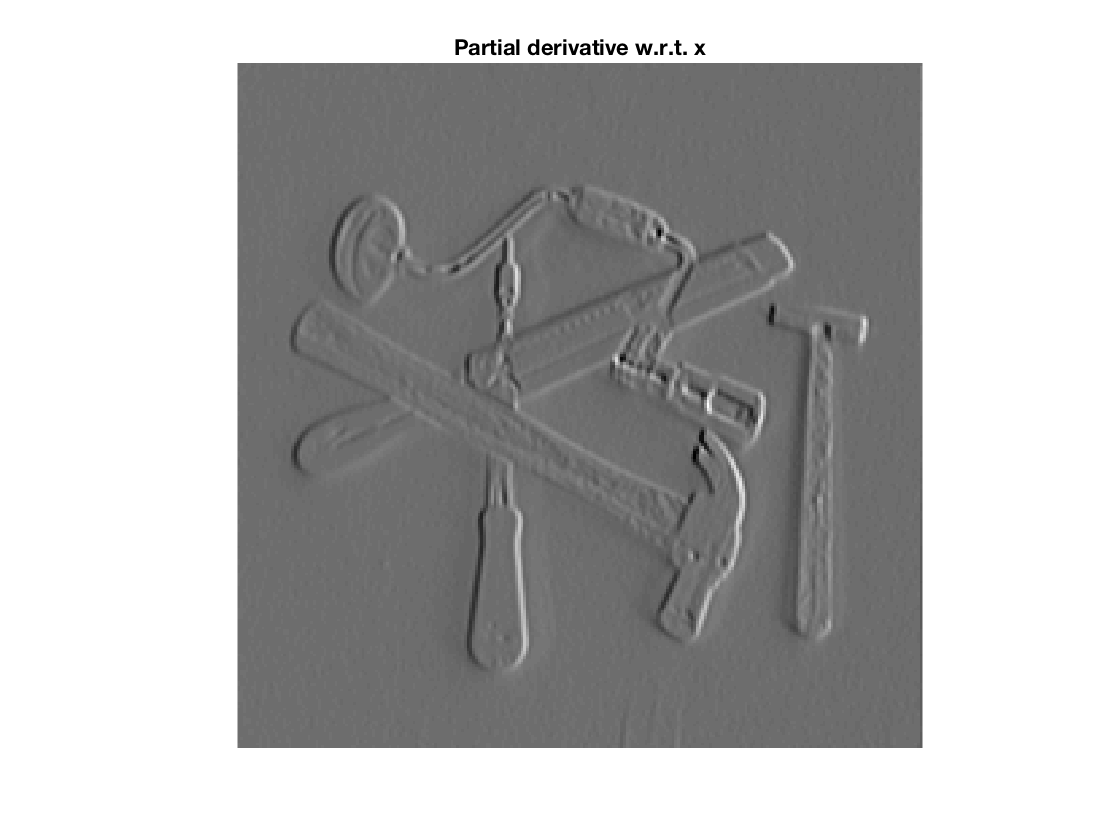


% Sobel (taking flip into account)
deltay = [1 2 1; 0 0 0; -1 -2 -1];
deltax = deltay';

dxtools = conv2(tools, deltax, 'valid');
dytools = conv2(tools, deltay, 'valid');

showgrey(dxtools);
title("Partial derivative w.r.t. x");

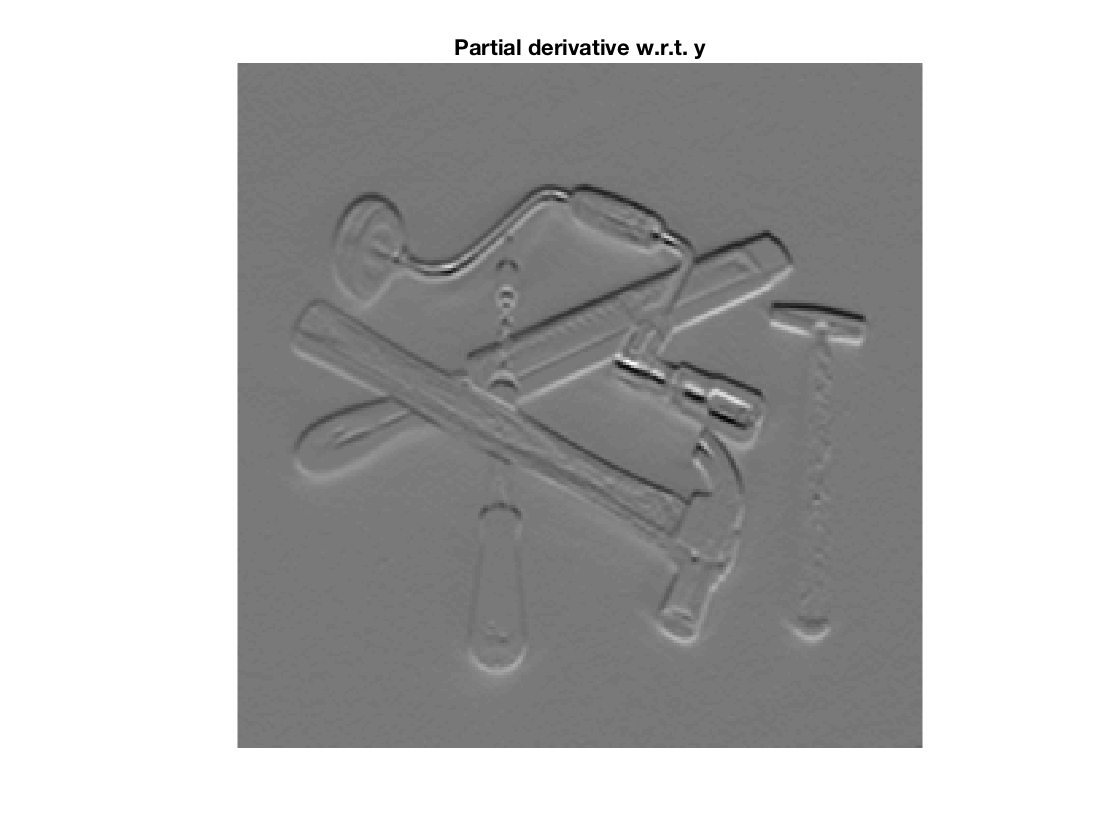


showgrey(dytools);
title("Partial derivative w.r.t. y");


display(size(tools));

   256   256



display(size(dxtools));

   254   254



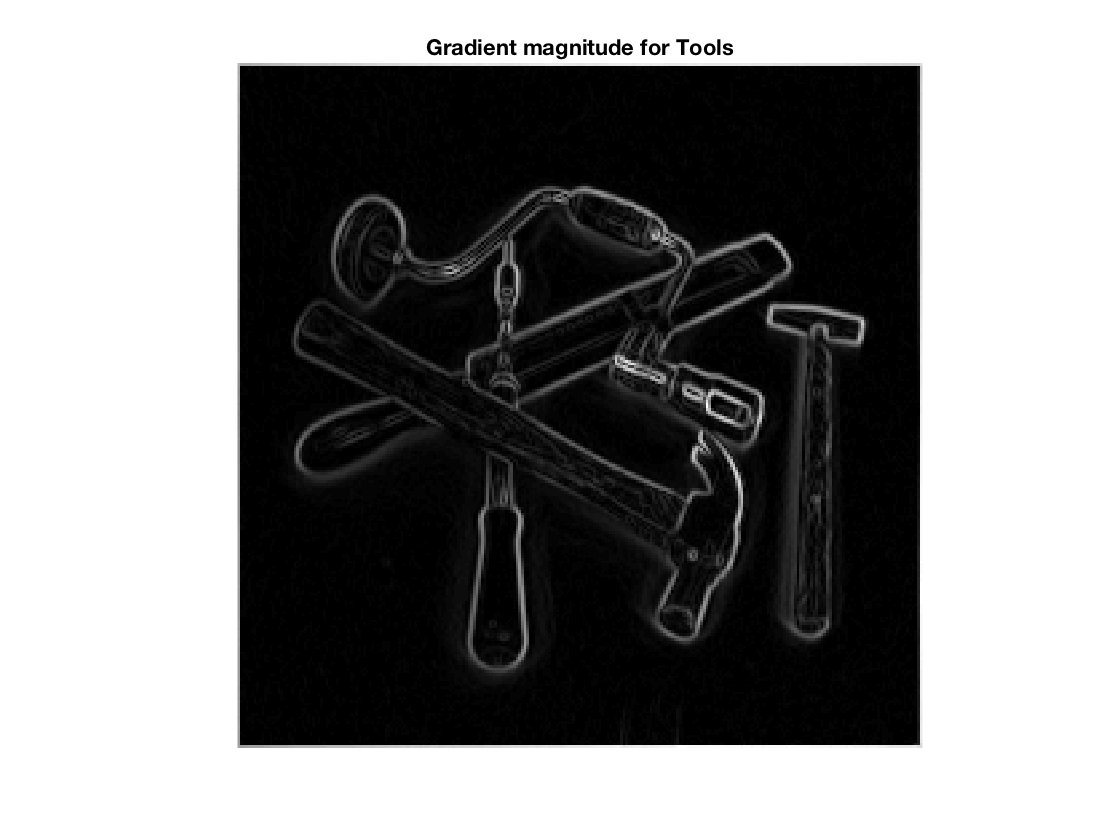

% Q2
house = godthem256;

gradmagntools = sqrt(Lv(tools));
showgrey(gradmagntools);
title("Gradient magnitude for Tools");

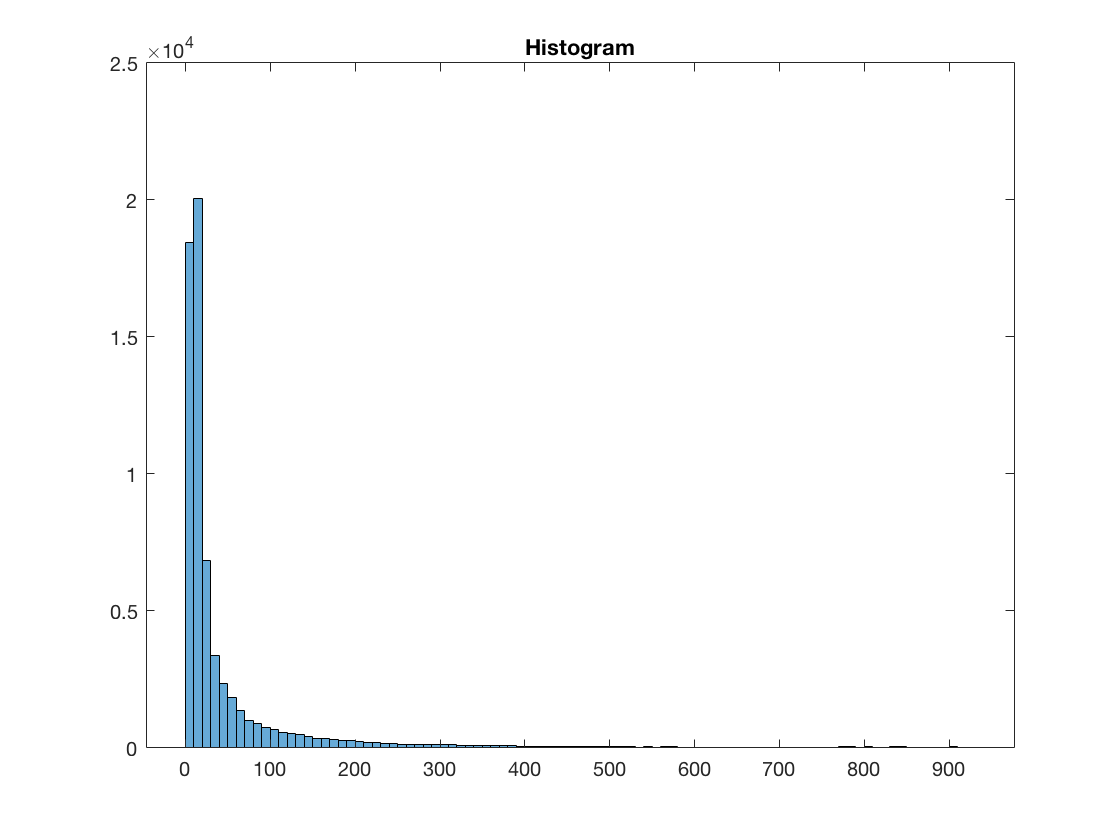

histogram(gradmagntools)
title("Histogram");

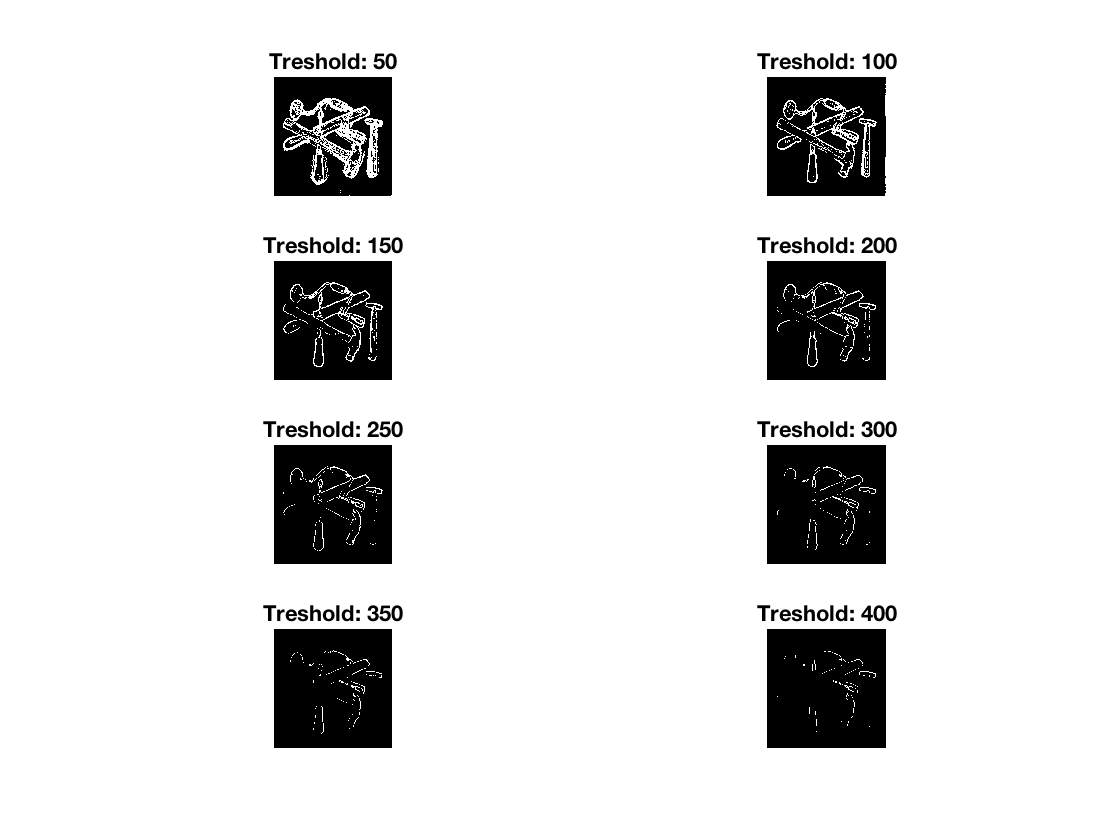


for i = 1:8
    subplot(4,2,i);
    thresh = i * 50;
    showgrey((gradmagntools - thresh) > 0);
    title(sprintf("Treshold: %d", thresh));
end

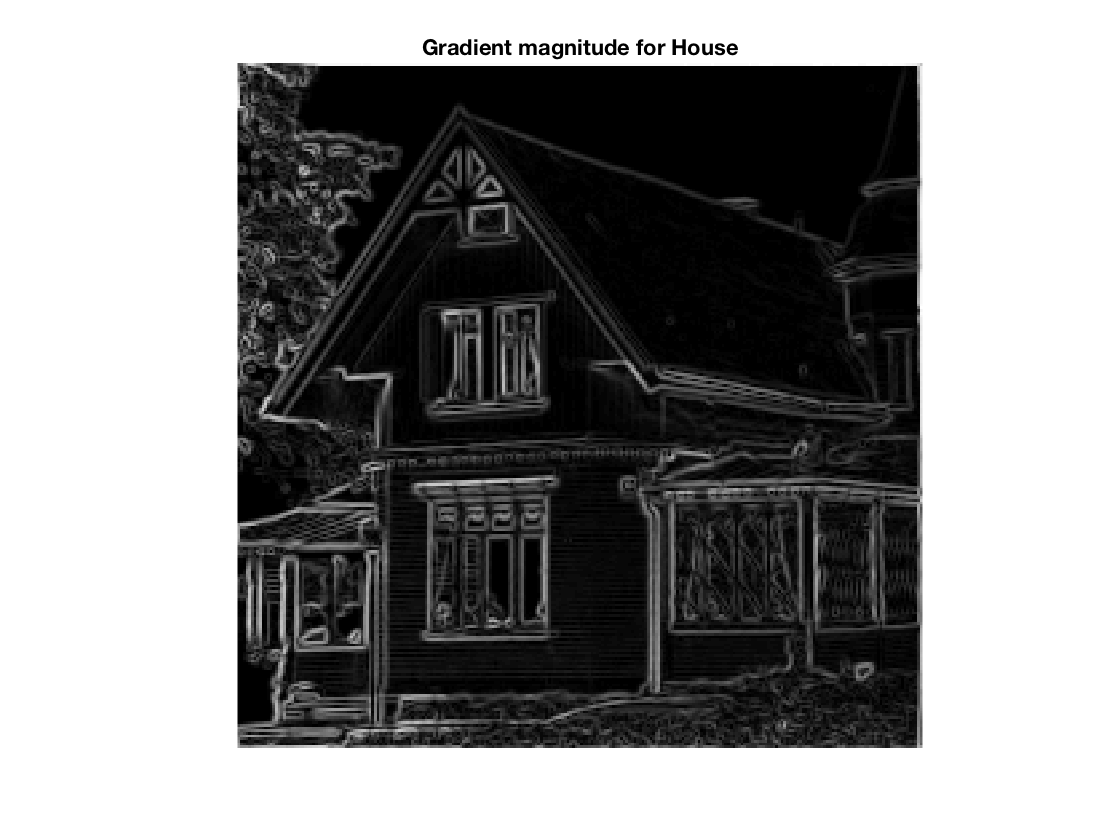

close all

gradmagnhouse = sqrt(Lv(house));
showgrey(gradmagnhouse);
title("Gradient magnitude for House");

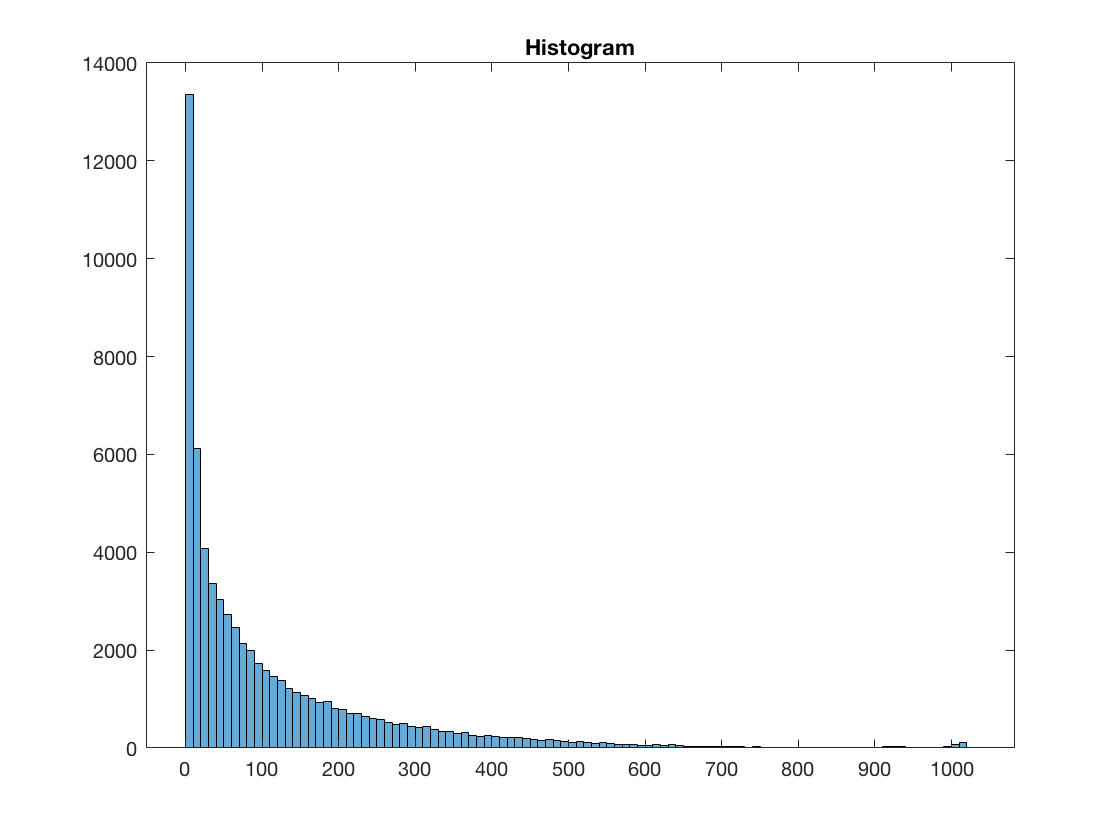

histogram(gradmagnhouse)
title("Histogram");

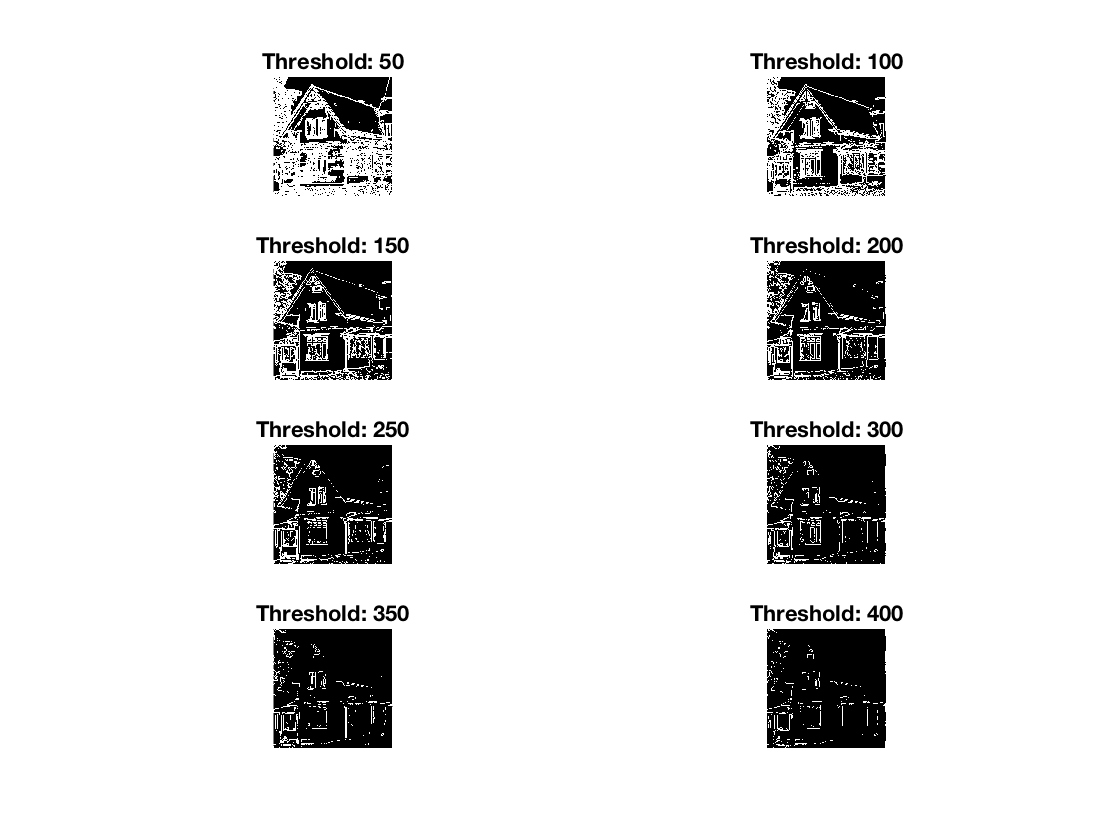


for i = 1:8
    subplot(4,2,i);
    thresh = i * 50;
    showgrey((gradmagnhouse - thresh) > 0);
    title(sprintf("Threshold: %d", thresh));
end